clear ; close all ; clc

syms s K_p K_d K_i

a = sym('a',[1 2]);
b = sym('b',[1 2]);

P = b(1) / (s + a(1))

$$P = \frac{b_{1}}{a_{1}+s}$$

% P = b(1) / (s^(2) + a(2)*s + a(1))
C = K_p + (K_i/s) + K_d*s

$$C = K_{p}+K_{d}\,s+\frac{K_{i}}{s}$$

G = P * C;
G = collect(simplify(expand(G)),s)

$$G = \frac{\left(K_{d}\,b_{1}\right)\,s^{2}+\left(K_{p}\,b_{1}\right)\,s+K_{i}\,b_{1}}{s^{2}+a_{1}\,s}$$

H = G / (1 + G);
H = collect(simplify(expand(H)),s)

$$H = \frac{\left(K_{d}\,b_{1}\right)\,s^{2}+\left(K_{p}\,b_{1}\right)\,s+K_{i}\,b_{1}}{\left(K_{d}\,b_{1}+1\right)\,s^{2}+\left(a_{1}+K_{p}\,b_{1}\right)\,s+K_{i}\,b_{1}}$$


all_sym = [a b K_p K_i K_d];
all_val = [1 1 1 1 3 0 1];

P = subs(P, all_sym, all_val)

$$P = \frac{1}{s+1}$$

C = subs(C, all_sym, all_val)

$$C = s+3$$

G = subs(G, all_sym, all_val)

$$G = \frac{s^{2}+3\,s}{s^{2}+s}$$

H = subs(H, all_sym, all_val)

$$H = \frac{s^{2}+3\,s}{2\,s^{2}+4\,s}$$


G_tf = sym2tf(G)


G_tf =
 
  s + 3
  -----
  s + 1
 
Continuous-time transfer function.



H_tf = sym2tf(H)


H_tf =
 
   s + 3
  -------
  2 s + 4
 
Continuous-time transfer function.




w = logspace(-2,1, 1000);
h = bodeplot(G_tf, H_tf, w)


h =

	resppack.bodeplot



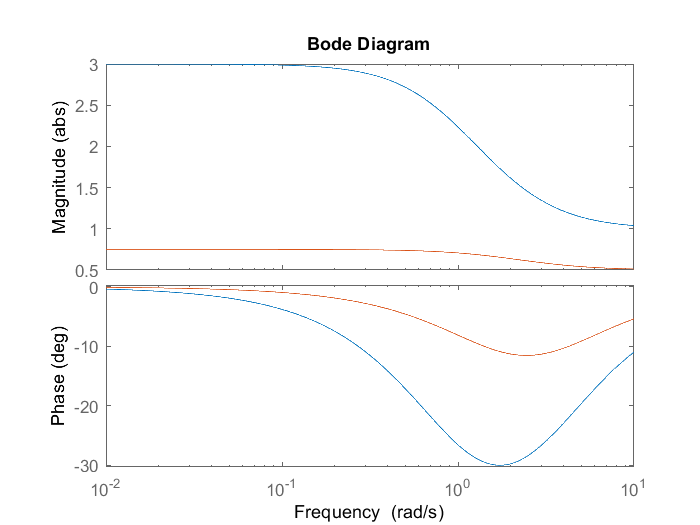

setoptions(h, 'FreqUnits', 'auto', 'MagUnits', 'abs');